# Drone Payload Structure Design and Analysis

In this project, you are optimizing drone arm design, including geometry and material selection, to maximize payload capacity while ensuring structural integrity under motor-induced loads. You will use MATLAB to perform force balance analysis and finite element modeling to quantitatively support your design solution.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Gather your starter assumptions and load the material properties into MATLAB.

- Propose at least two drone arm designs

- Perform a thrust-to-weight analysis to evaluate each of your designs across all material options. Your design must meet a minimum payload requirement and safety standards.

- Perform finite element analysis across all design and material options.

- Recommend a final design solution.

## Break Down the Problem

In the space below, define the problem statement:

The goal is to design a drone arm that can safely handle motor-induced loads while maximizing payload capacity. Two structurally distinct designs must be created and analyzed using finite element analysis (FEA), thrust-to-weight analysis, and provided drone arm material properties. The designs must meet project-specified minimum payload and thrust-to-weight ratio requirements, as well as a minimum factor of safety (FOS) requirement to ensure safe operation.

List the requirements, constraints, and success criteria for the project:

    Requirements:

- Minimum payload requirement: 0.5 kg

- Minimum thrust-to-weight ratio: 2:1

- Minimum FOS: 1.5

    Constraints: 

- Quadcopter configuration: 4 motors and 4 propellers

- Motor mass: 0.065 kg per motor

- Thrust per motor: 1 kg of thrust

- Maximum total thrust: 4 kg of thrust

- Maximum drone arm mass: 0.125 kg per arm

- Total mass of components excluding drone arms and payload: 1.0 kg

    Success Criteria:

- Drone arm must maximize payload capacity while meeting minimum thrust-to-weight ratio and minimum FOS.

- Drone arm must minimize mass.

- Drone arm must limit maximum stress and displacement.

- Drone arm should minimize material cost (optional).

What is your proposed solution?

    We propose two possible drone arms. The first drone arm design will use a hollow oval cross-section and one drone body attachment points. The second drone arm will use a triangular truss design and contain three drone body attachment points, and the truss design will contain solid outer supports and solid inner web members.

List the steps you will need to take to achieve your proposed solution:

- Sketch out two drone arms, making sure to include rough dimensions, a motor attachment point, and drone body attachment point(s).

- Create the 3D models from sketches using CAD software. Export these models as STL for analysis.

- Analyze both drone arms and provide initial thrust-to-weight ratio results for each drone arm and material combination.

- Perform FEA on the drone arms and record x-, y-, and z- displacement as well as Von Mises stress. Ensure drone arms meet the minimum FOS.

- Use an optimization function that minimizes mass and material cost (optional).

- Display required results. This includes thrust-to-weight and FEA results for each drone arm and material combination.

- Analyze the FEA data and compare the advantages/disadvantages of each drone arm. Comparison should include payload capacity, arm mass, FOS, Von Mises stress, and displacement differences.

- Optional: Include material cost comparison.

- Submit our final report which includes a drone arm design recommendation.

What challenges do you face in the process of achieving the solution?

- Material selection and tradeoff analysis: Each material has different properties that give it distinct advantages and disadvantages. The challenge arises from selecting a material with advantageous properties that align with the drone arm requirements while minimizing disadvantageous properties. 

- Drone arm design and CAD: The dimensions of the drone arm affect mass, stress, and displacement, which makes dimension selection a vital part of the drone design process. Additionally, the selected dimensions must be realistic to ensure that the drone arm can be manufactured. Due to the team's limited experience in design, the selection of proper dimensions is a challenge.

- FEA setup: The team members have limited experience with FEA. As a result, properly setting up FEA in MATLAB and accurately interpreting results becomes a challenge. 

## Task 1: Gather your starter assumptions and load material properties

Load the provided `droneArmMaterials.mat` file into MATLAB. This contains a data struct with the material properties for six different materials commonly used for drones (carbon fiber composite, aluminum alloy, fiberglass composite, PLA plastic, ABS plastic, and wood). For each material, you have been provided the following information:

- Density ($\rho$), in $\frac{\mathrm{kg}}{m^3 }$

- Young's Modulus ($E$) in Pa

- Poisson's ratio ($\nu$), unitless

- Yield strength, in Pa

- Average cost per meter in US dollars

For this project, you can assume the following design parameters:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg thrust

- Acceleration due to gravity: $g=9\ldotp 81\;\frac{m}{s^2 }$ 

- Total weight of the drone components without the arms or the payload: 1kg 

The breakdown of the weight of each drone component is as follow:

- Battery = 0.3kg

- Each motor = 65g, 4 motors = 0.26kg

- Each propeller = 10g, 4 propellers = 0.04 kg

- Each electronic speed controller = 30g, 4 electronic speed controllers = 0.12 kg

- Flight controller and electronics = 0.05kg

- Receiver/GPS = 0.03kg

- Drone frame (center body) excluding arms = 0.2kg

addpath('functions');
load(fullfile('data', 'droneArmMaterials.mat'));

% Arrays of material data
[names, rho, E, nu, yieldStrength, cost] = materialDataExtractor(materials);
nMaterials = numel(materials);

g = 9.81;         % gravitational acceleration [m/s^2]

nMotors = 4;              % number of motors
nProps = 4;               % number of propellers
nArms = 4;                % number of arms

thrustPerMotor_kg = 1;
maxTotalThrust_kg = nMotors * thrustPerMotor_kg;

m_battery = 0.30;            % battery [kg]
m_motors = nMotors * 0.065;  % 4 motors, 65 g [kg]
m_props = nProps  * 0.010;   % 4 propellers, 10 g [kg]
m_esc = 4 * 0.030;           % 4 ESCs, 30 g [kg]
m_flightCtrl = 0.05;         % flight controller + electronics [kg]
m_receiverGPS = 0.03;        % receiver / GPS [kg]
m_frame = 0.20;              % center body, excludes arms [kg]

baseMass = m_battery + m_motors + m_props + m_esc + m_flightCtrl + m_receiverGPS + m_frame;

motorMass = 0.065;               % [kg]

payloadMin = 0.5;   % minimum required payload [kg]
TWmin = 2;          % minimum thrust-to-weight ratio
FOSmin = 1.5;       % minimum factor of safety

% Net transverse tip load for the Task 3 stress pre-screen [N]
thrustPerMotor_N = thrustPerMotor_kg * g;
motorWeight_N = motorMass * g;
F_tip_N = thrustPerMotor_N - motorWeight_N;   % net upward load bending the arm
FOSmin_preFEA = 2.0;                          % FOS accounting for hand calculation errors

## Task 2: Propose at least two drone arm designs

Develop at least two distinct drone arm designs by drawing clear, neatly labeled sketches that show key geometric features, including:

- Overall shape (e.g. beam, tube, truss structure)

- Dimensions (length, width, thickness)

- Motor mount location

- Where the arm connects to the drone body 

The two designs should be meaningfully different from each other (e.g. different geometries or structural strategies) and not just small variations of the same idea.

Navigate to the 'Insert' tab and insert pictures of your sketches in the space below (hand-drawn or digital). Include a short design description for each sketch that includes:

- Geometry (e.g. solid beam, hollow tube, beam with trusses)

- Why you chose this design

- How it might perform under load

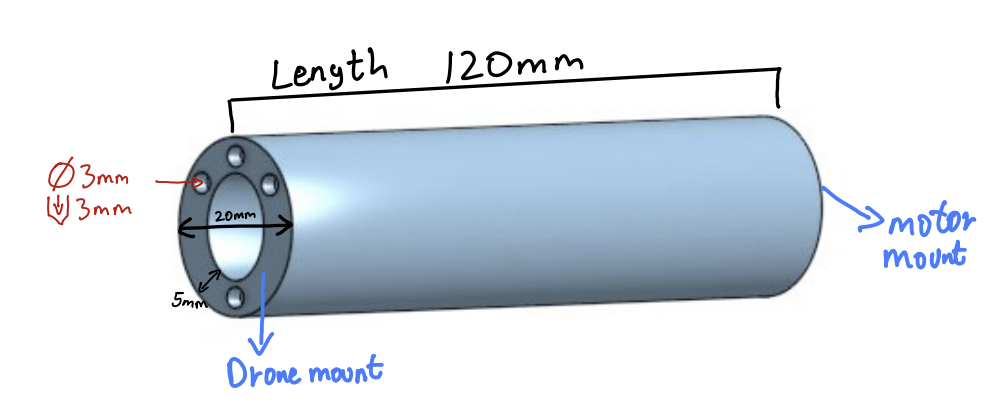

Geometry: Hollow circular tube, 120 mm long, 30 mm outer diameter, 20 mm inner diameter (5 mm uniform wall). Motor mounts at the tip via four Ø3 mm × 3 mm holes; the arm bolts to the drone body at the base end through a matching four-hole pattern.

Why we chose it: A closed tube distributes bending load around the full perimeter and resists torsion from motor and propeller reaction. Hollowing the center removes material near the neutral axis, where bending stress is lowest, so very little strength is given up for the weight saved. The circular section behaves identically no matter the orientation, which prevents assembly error.

How it performs under load: Acts as a cantilever beam, with stress peaking at the top and bottom outer surfaces where the arm meets the body. Our initial design used a thinner wall, but FEA showed extreme tip deflections, which we judged too flexible for stable flight. Increasing the wall to 5 mm brought deflection down greatly at the cost of additional mass.

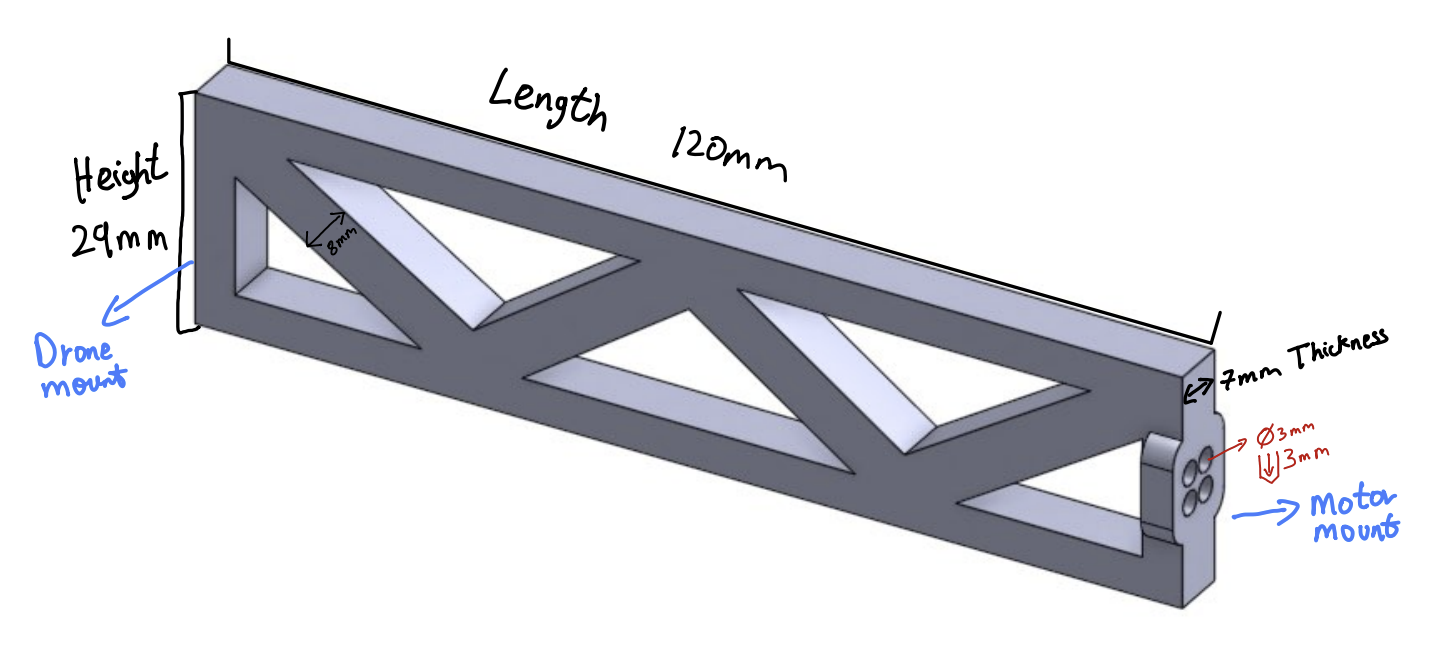

Geometry: Flat truss plate, 120 mm long, 29 mm tall, 7 mm thick, with 8 mm wide members forming triangular bays. Motor mounts at the tip through four Ø3 mm × 3 mm holes in a raised boss; the base end attaches to the drone body across the full-height end face.

Why we chose it: Inspired by bridge trusses, which achieve high strength per unit weight. The triangular pattern removes material from regions carrying little load while keeping material along the top and bottom edges where bending demand is highest, so the arm occupies a large structural envelope while using far less material than a solid beam of the same size.

How it performs under load: Bending is resolved into a tension–compression couple in the top and bottom chords, with the diagonals carrying shear between them. Our initial design used 3 mm members, but FEA showed factor of safety below the 1.5 requirement for [list materials], driven by stress concentrations at the joints that our analytical model did not capture. Widening the members to 8 mm resolved this across all six materials.

## Task 3: Perform thrust-to-weight analysis across all design and material options

Write a MATLAB function that will perform a thrust-to-weight analysis across all design and material options. This analysis will help you evaluate which drone arm design and which material optimizes payload capacity while meeting suggested safety requirements. 

- Your design must support a minimum payload of 0.5kg. 

- Your design must meet a thrust-to-weight ratio of at least 2:1 to ensure safe and stable flight. This safety standard is widely used in drone design. Conceptually, it means that the drone's maximum thrust must be at least twice its weight. This ensures stable hovering and maneuvering with a safety margin. Note that the thrust-to-weight safety margin is a system-level safety standard for drone flight that is distinct from the structural safety factor of the drone arms (which you will evaluate later through finite element analysis).

- Your goal is calculate maximum payload capacity for each design and material option (i.e. what is the heaviest payload your drone design could carry while still allowing the drone to safely take off?)

Ensure that the results of your analysis can be readily interpreted, e.g. in the form of a summary table or plot.

Note: if you have two drone arm designs, the expected output should be 12 payload capacity estimates (2 designs across 6 materials options).

% Bundling Task 1 constants for armAnalysis
params.baseMass = baseMass;
params.nArms = nArms;
params.maxTotalThrust_kg = maxTotalThrust_kg;
params.TWmin = TWmin;

% Arm dimensions [mm]
% Length fixed to 120mm for propeller clearance
dims.oval  = struct('L',120, 'W',30, 'H',30, 't',1.5);
dims.truss = struct('L',120, 'H',25, 'd',7.5, 'nBays',4);

designs = ["oval", "truss"];

% Preallocate results
nRows = numel(designs) * nMaterials;
Design = strings(nRows,1);
Material = strings(nRows,1);
ArmMass_g  = zeros(nRows,1);
MaxPayload_kg = zeros(nRows,1);
MeetsPayload = false(nRows,1);
MaxStress_MPa = zeros(nRows,1);
FOS_est = zeros(nRows,1);
MeetsFOS = false(nRows,1);

row = 0;
% fill one table row per design-material combination
for d = 1:numel(designs)
    for m = 1:nMaterials
        row = row + 1;
        [armMass, maxPayload] = armAnalysis(designs(d), dims.(designs(d)), rho(m), params);
        [maxStress, FOS] = armStress(designs(d), dims.(designs(d)), F_tip_N, yieldStrength(m));
        MaxStress_MPa(row) = maxStress / 1e6;              % peak stress, Pa -> MPa
        FOS_est(row) = FOS;                                % safety factor = yield / maxStress
        MeetsFOS(row) = FOS >= FOSmin_preFEA;              % pass hand-calc target of 2.0 (buffer above the 1.5 requirement)
        Design(row) = designs(d);                          % "oval" or "truss" for this row
        Material(row) = names(m);                          % material name for this row
        ArmMass_g(row) = armMass * 1000;                   % arm mass, kg -> g
        MaxPayload_kg(row) = maxPayload;                   % max payload at 2:1 thrust-to-weight [kg]
        MeetsPayload(row) = maxPayload >= payloadMin;      % pass 0.5 kg minimum
    end
end

% prints table
resultsTW = table(Design, Material, ArmMass_g, MaxPayload_kg, MeetsPayload, ...
                  MaxStress_MPa, FOS_est, MeetsFOS)

resultsTW = 12×8 table
    Design                Material                ArmMass_g    MaxPayload_kg    MeetsPayload    MaxStress_MPa    FOS_est    MeetsFOS
    _______    _______________________________    _________    _____________    ____________    _____________    _______    ________

    "oval"     "Carbon Fiber Composite (CFRP)"     25.786         0.89686          true             1.2074       496.92      true   
    "oval"     "Aluminum Alloy"                    43.514         0.82594          true             1.2074       227.75      true   
    "oval"     "Fiberglass Composite (GFRP)"       30.621         0.87752          true             1.2074       248.46      true   
    "oval"     "PLA Plastic"           

## Task 4: Perform finite element analysis across all design and material options

Perform finite element analysis (FEA) across all design and material options to evaluate the structural safety factor of your drone arm design. To simplify the task, you will perform the FEA only on a single drone arm.

Using a CAD software of your choice, first create a 3D model of one drone arm for each of your designs. Be sure your model can be exported as a STEP or STL file for analysis in MATLAB.

- Recommended CAD software options: Tinkercad, Onshape, Fusion 360, Solidworks (most have free versions)

Import your model into MATLAB and perform FEA. In your FEA model, you should model and apply two loads to the drone arm: upward thrust force from the motor and downward weight of the motor.

- Helpful resources: [online tutorial](https://matlabacademy.mathworks.com/details/introduction-to-finite-element-analysis-with-matlab/otmlfea), documentation for [Structural Mechanics](https://www.mathworks.com/help/pde/structural-mechanics.html) and [Partial Differentiation Equation Toolbox](https://www.mathworks.com/help/pde/index.html?s_tid=CRUX_lftnav), and [example workflow](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

For each design and material combination, you should report the overall maximum displacement, maximum stress, and factor of safety and include visualizations of the x-, y-, and z-displacement and Von Mises stress. Ensure that your results are presented for easy interpretation (e.g. present a table with numerical results, clearly labeled subplots for the visualizations).

- The factor of safety compares how strong a material is to how much stress it experiences, indicating whether a design is safe under the given loads. For this project use the equation: $\mathrm{FoS}=\frac{\mathrm{Material}\;\mathrm{Yield}\;\mathrm{Strength}\;\left(\mathrm{Pa}\right)}{\mathrm{Maximum}\;\mathrm{von}\;\mathrm{Mises}\;\mathrm{Stress}}$. Yield strength indicates how much stress a given material can withstand before permanently deforming. Maximum von Mises stress (derived from your FEA model) is a measure of how much stress your design experiences under the applied loads.

- A typical engineering safety margin for FoS is ~1.5-2+

- This [example](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html) demonstrates the plots you are asked to include in your results

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented. Use the
% suggested steps below as a guide for the FEA workflow, but make sure to evaluate all design
% and material options

% STEP 1: Import drone arm geometry into MATLAB, visualize the geometry to
% identify  key faces (e.g. tip face)

% STEP 2: Define material properties

% STEP 3: Apply boundary conditions (fix base of arm where it would be
% attached to drone body)

% STEP 4: Apply the upward thrust force (motor force)
% Define the thrust force, convert force to surface traction, apply
% surface traction to the appropriate face in the appropriate direction

% STEP 5: Apply downward motor weight
% Define motor weight, convert to traction, apply to the appropriate face
% in the appropriate direction

% Optional: combine the two loads into a single net traction rather than
% applying them separately
% Optional: include the force of gravity on the arm

% STEP 6: Solve the FEA model (using the solve function) and store the
% results for analysis below.

% STEP 7: Get numerical results 
% The results object generated above contain fields for displacement and
% stress. Report maximum displacement magnitude and maximum Von Mises
% stress for each material-design combination. Use the maximum Von Mises
% stress and given material yield strength to compute factor of safety for
% each material-design combination. Present your results for easy
% comparison (e.g. summary table or plot).

% STEP 8: Visualize your results
% Create plots to visualize the x-, y-, and z-displacement and the von
% Mises stress.
% Hint: Use the Live Editor task "Visualize PDE Results" or the function
% pdeplot3D


## Interpretation of Results - Final Recommended Design Solution

Using the results of your thrust-to-weight analysis and finite element analysis, recommend a final drone arm design that meets all required constraints. Your recommendation should clearly identify the selected design (arm geometry and material choice), make use of quantitative results to justify your decisions, demonstrate that the design meets the constraints, explain the trade-offs considered, and include comparisons to alternative designs.

What are some limitations of your work?

What are practical next steps?